# One-Legged Hopping Robot

#### Parameters

M1=1; % Leg mass [kg]
M2=10; % Body mass [kg]

I1=1; % Leg moment of Inertia [kg-m^2]
I2=10; %Body moment of Inertia [kg-m^2]

r1=0.5; % [m]
r2=0.4; % [m]

k0=1; % [m]
KL=10^3; % [Nt/m]

KL2=10^5; % [Nt/m]
BL2=125; % [Nt-s/m]

KG=10^3; % [Nt/m]
BG=75; % [Nt-s/m]

H=0.5; %[m]
H2=0.2;
T2_change = 10; % Time at which the height reference is changed [s]


g=9.8;

#### Initial Conditions

chi_0 = 0.07;

ini_theta1=0;
ini_theta1_d=0;

ini_theta2=0;
ini_theta2_d=0;

ini_w=k0 - chi_0;
ini_w_d=0;

ini_x0=0;
ini_x0_d=0;

ini_y0=0.02;
ini_y0_d=0;

ini_x1=ini_x0+r1*sin(ini_theta1);
ini_x1_d=0;

ini_y1=ini_y0+r1*cos(ini_theta1);
ini_y1_d=0;

ini_x2=ini_x1+r2*sin(ini_theta2);
ini_x2_d=0;

ini_y2=ini_y0+ini_w+r2*cos(ini_theta2);
ini_y2_d=0;



#### Theta1_desired for torque control (equation 1)

theta1_des=0;

**Desired system energy to jump to height H (equation 14)**

desired_energy = M1*g*(H+r1) + M2*g*(H+k0+r2);
desired_energy2 = M1*g*(H2+r1) + M2*g*(H2+k0+r2);

**SIMULINK**

simtime=10; %simulation time
SimDec=sim('HoppingModel_Vertical',simtime); %Execution of the simulation in Simulink

Found algebraic loop containing: 
HoppingModel_Vertical/One_Legged_Robot/Subsystem_x/Fcn (algebraic variable)
HoppingModel_Vertical/One_Legged_Robot/Subsystem_x/x_dd
HoppingModel_Vertical/One_Legged_Robot/Subsystem_y/Fcn
HoppingModel_Vertical/One_Legged_Robot/Subsystem_y/y_dd
HoppingModel_Vertical/One_Legged_Robot/Subsystem_w/Fcn


PLOTS

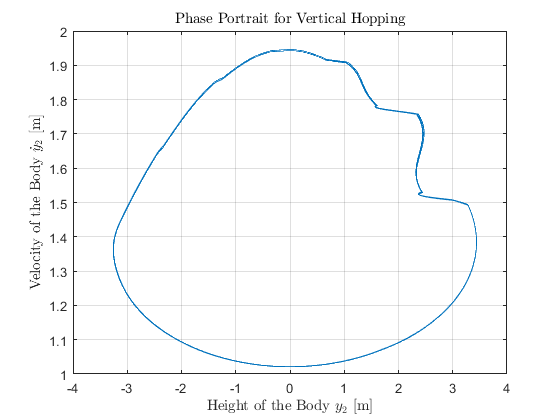

figure(1)
plot(SimDec.y2d.signals.values(6000:end),SimDec.y2.signals.values(6000:end))
grid on
title('Phase Portrait for Vertical Hopping','Interpreter','latex')
xlabel('Height of the Body $y_2$ [m]','Interpreter','latex')
ylabel('Velocity of the Body $\dot{y}_2$ [m]','Interpreter','latex')